%Loading the Data
if not(exist('mnist_train', 'var'))
    load data\mnist_train.csv
end
if not(exist('mnist_test', 'var'))
    load data\mnist_test.csv
end

%Showing n-th Image
n = 1;
img_matrix = reshape(mnist_train(n, 2:end), [28 28])';
digit = mnist_train(n, 1)

digit = 5

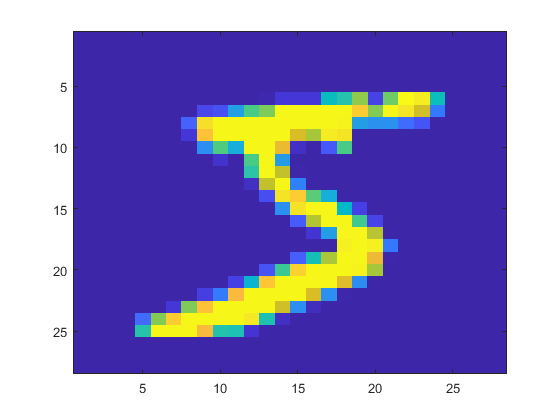

image(img_matrix)

%One Hot Encoding of Labels
labels = mnist_train(:, 1);
labels = categorical(labels);
labels = onehotencode(labels, 2);

%Building the Neural Network
layers = [784 16 10]

layers =    784    10


num_layers = length(layers);
num_hidden = num_layers-2;

weights = {};
for i = 2:length(layers)
    weights = {weights{:}, -1 + 2.*rand(layers(i-1), layers(i))'};
end

biases = {};
for i = 2:length(layers)
    biases = {biases{:}, -1 + 2.*rand(layers(i),1)};
end

%Variables
lr = 0.05;
epochs = 10;

%Training the Neural Network
for epoch = 1:epochs
    epoch
    for iter = 1:length(mnist_train)
        %Setting Activations
        activations = {1/256 * mnist_train(iter, 2:end)'};
        for i = 2:length(layers)
            activations = {activations{:}, zeros(layers(i), 1)};
        end
        
        %Pass Forward
        for l = 2:length(layers)
            activations{l} = sigmoid(weights{l-1} * activations{l-1} + biases{l-1});
        end
        
        %Calculating Error
        error = (labels(iter,:)' - activations{end});
        
        %Propagate Error Back
        delta = {error .* dsigmoid(weights{num_layers-1} * activations{num_layers-1} + biases{num_layers-1})};
        for l = num_hidden:-1:1
            delta = {(weights{l+1}' * delta{1}) .* dsigmoid(weights{l} * activations{l} + biases{l}), delta{:}};
        end
        
        %Update Weights and Biases
        for l = length(layers)-1:-1:1
            weights{l} = weights{l} + lr * delta{l} * activations{l}';
            biases{l} = biases{l} + lr * delta{l};
        end
        
    end
    
    %Verifying the accuracy 
    right = 0;
    wrong = 0;
    for iter = 1:length(mnist_test)
        %Setting Activations
        activations = {1/256 * mnist_test(iter, 2:end)'};
        for i = 2:length(layers)
            activations = {activations{:}, zeros(layers(i), 1)};
        end
        
        %Pass Forward
        for l = 2:length(layers)
            activations{l} = sigmoid(weights{l-1} * activations{l-1} + biases{l-1});
        end
        
        %Get Prediction
        [value, index] = max(activations{end});
        pred_label = index - 1;
        
        %Check Prediction
        if pred_label == mnist_test(iter, 1)
            right = right + 1;
        else
            wrong = wrong + 1;
        end
    end
    
    accuracy = right/(right+wrong)
end

epoch = 1

accuracy = 0.6493

epoch = 2

accuracy = 0.7398

epoch = 3

accuracy = 0.7447

epoch = 4

accuracy = 0.7497

epoch = 5

accuracy = 0.8349

epoch = 6

accuracy = 0.8372

epoch = 7

accuracy = 0.8381

epoch = 8

accuracy = 0.8390

epoch = 9

accuracy = 0.8391

epoch = 10

accuracy = 0.8396

%Defining Functions

function y = sigmoid(z)
    y = (1./(1+exp(-z)));
end

function y = dsigmoid(z)
    y = sigmoid(z) .* (1-sigmoid(z));
end